clear; clc;
csv = readmatrix("csv/step_test.csv");

data_length = length(csv(:,2))-1

data_length = 3013

time = csv(2:data_length+1, 2);    % мкс
q_orig = csv(2:data_length+1, 3) * pi/180;  % рад
w_orig = csv(2:data_length+1, 4) * pi/180;  % рад/c
dw_orig = csv(2:data_length+1, 5) * pi/180;  % рад/c^2
input = csv(2:data_length+1, 6) / 100 * 12;    % В
current = csv(2:data_length+1, 7);  % А

t_start = time(1);
time = (time - t_start)/1000000;    % с

dt_sum = 0;
for k = 2:data_length
    dt = time(k) - time(k-1);
    dt_sum = dt_sum + dt;
end

dt = dt_sum/(data_length-1)

dt = 0.0099


dw_orig = smooth(dw_orig, 2);
current = smooth(current, 6);

syms K t Lam w x

I = Lam/K*w

$$I = \frac{\mathrm{Lam}\,w}{K}$$


y = 0.065*sin(0.45*x)

$$y = \frac{13\,\sin\left(\frac{9\,x}{20}\right)}{200}$$

y1 = 0.065*0.3*x+0.008

$$y1 = \frac{39\,x}{2000}+\frac{1}{125}$$

y2 = -0.065*0.3*(x-7)+0.008

$$y2 = \frac{289}{2000}-\frac{39\,x}{2000}$$

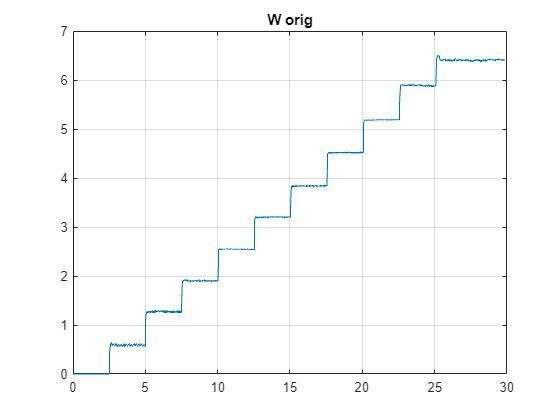


figure;
plot(time, w_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

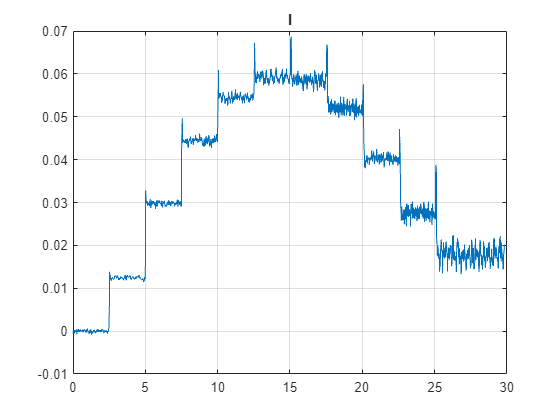


figure;
plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

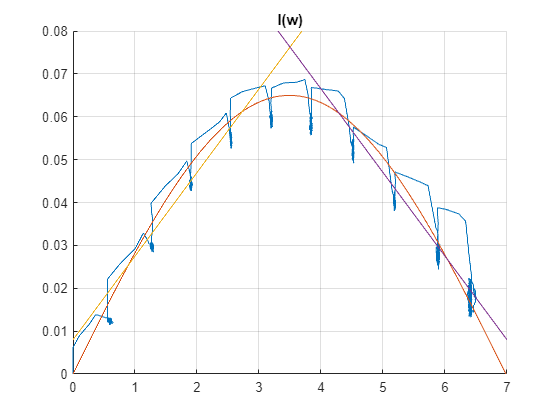


figure;
hold on
plot(w_orig, current)
fplot(y)
fplot(y1)
fplot(y2)
hold off
title("I(w)")
% xlim("auto")
% ylim("auto")
xlim([0 7])
ylim([0 0.08])
grid on